# Pendolo Invertito

Iniziamo settando i parametri del sistema ad alcuni valori iniziali:

clear;
clearvars;
%x,t,m,M,l,F
dt = (0:0.05:40);
m = 0.1;%kg
M = 1;%kg
l = 0.5;%m
g = 9.81; %m/s^2
F = 1;%N

Infine le condizioni iniziali e la precisione del risolutore:

x0 = [0,0,0,0];% theta_0 = pi/6, velocità angolare = 0 posizione iniziale=0
% velocità iniziale 2 m/s
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

Chiamiamo ora il nostro ode45:

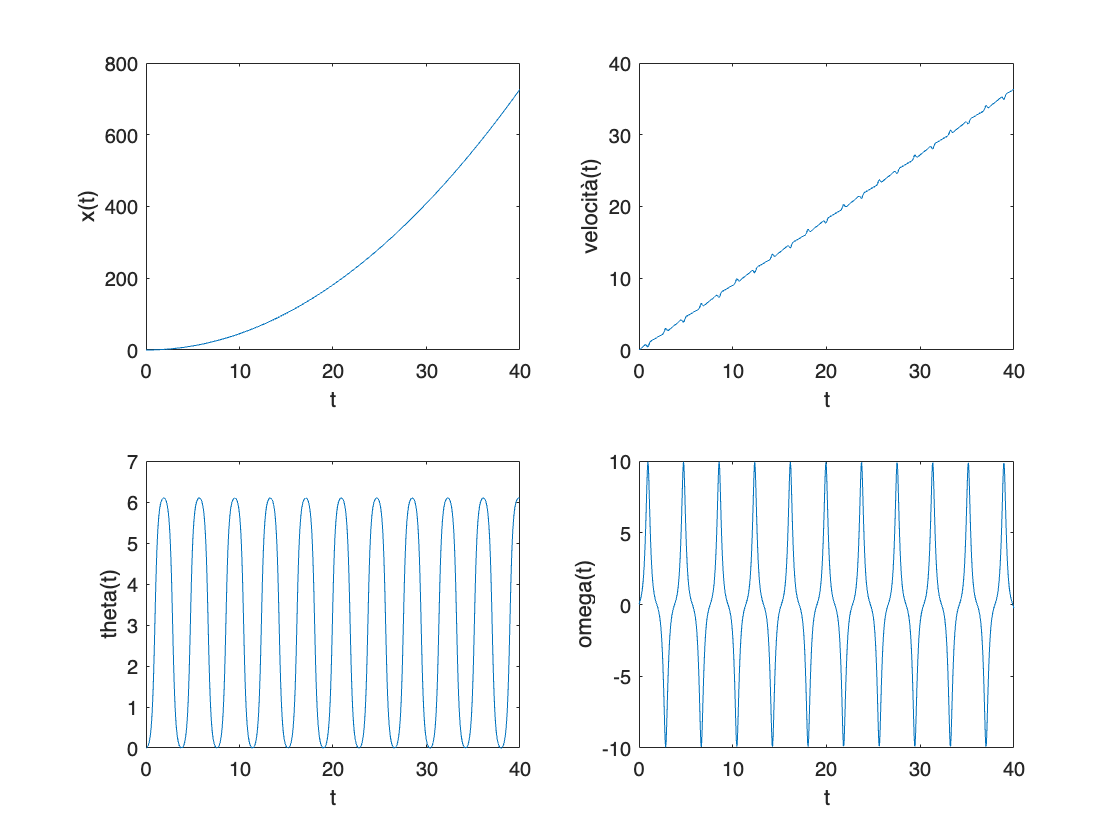

[t,x] = ode45(@(t,x)Inv_pend(x,t,m,M,l,F),dt,x0,opts);
figure;
subplot(2,2,1)
plot(t,x(:,3))
xlabel("t");
ylabel("x(t)");
subplot(2,2,2);
plot(t,x(:,4))
xlabel("t");
ylabel("velocità(t)");
subplot(2,2,3);
plot(t,x(:,1));
xlabel("t");
ylabel("theta(t)");
subplot(2,2,4);
plot(t,x(:,2));
xlabel("t");
ylabel("omega(t)");